# Prediction concepts for control101

This livescript is a brief manual in support of the app ***prediction_concepts_control101.mlapp***.   This is a simple interface to understand both how prediction underpins control decision making and also how, with poor choices of horizons, these decisions may be poorly thought through.

Predictions are core to the advanced control technique of model predictive control (MPC) and thus understanding their role is essential before engaging with MPC.

- For more help on how to get the most of this app, please see the videos [here](https://www.youtube.com/playlist?list=PLs7mcKy_nInHEjth9P3m_bxd6D24IVSzz).

- For more information on the supporting files for MPC, please see the following livescripts: ***mpcsourcecode_control101.mlx.***

- For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- MPC context

- Forming predictions

- Assessing expected performance

- Interface and user interaction

## 1. MPC context

MPC is a control strategy which bases the choice of control input u(k) on the expected system output behaviour y(k), that is the system predictions. In essence, at each sampling instant:

- Postulate a possible future sequence of inputs u(k), u(k+1), ... .

- Evaluate the corresponding future outputs y(k+1|k), y(k+2|k),... .

- Assign some performance measure J(k) to the input/output prediction pair.

- Through some appropriate search over a range of possible future input sequences, determine the one which gives the best expected performance and use the first element of this sequence, that is u(k).

This manual goes through these steps concisely and also introduces an app designed to help students understand these and the basics of MPC design.

**NOTE**: Notation x(k+n|k) means the prediction n-steps ahead, that is a future sample k+n, made at sample k.

## 2. Forming predictions

For simplicitly this app focuses on linear SISO models, although the same principles can be used for non-linear and MIMO models, albeit the coding is somewhat more challenging. Without going into details it can be shown that the predictions can be evaluated as matrix vector multiplication, that is:


$$\left\lbrack \begin{array}{c}
y\left(k+1|k\right)\\
y\left(k+2|k\right)\\
\vdots \\
y\left(k+n|k\right)
\end{array}\right\rbrack =H\left\lbrack \begin{array}{c}
u\left(k|k\right)\\
u\left(k+1|k\right)\\
\vdots \\
u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
u\left(k-1\right)\\
u\left(k-2\right)\\
\vdots \\
u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(\textrm{kk}\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack +L\;o$$


where the matrics $H,P,Q$ depend upon the system model and the term $L\;o$ is to deal with disturbances and parameter uncertainty and thus ensure unbiased prediction in the steady-state (see references for details).

**Remark**: As will be seen from the references, there are multiple different mechanisms for forming predictions depending on the model format, characterisation of uncertainty and so forth. Such details are not important here and is suffice to comment that they reduce to a conceptually equivalent structure.

## 3 Assessing expected performance

The user needs to select the future inputs which will lead to the best predicted behaviour. 

### 3.1 Human decision making

Humans use prediction all the time when we make decisions. In simple terms we ask ourselves which decision is most likely to lead to the desired outcome. However, humans are less good at quantifying this. For example, look at the two predictions in the figure shown on the right. Which of this is a better response and why? Of course the answer is not clearly defined: do you prioritise fast movement to the steady-state or would you prefer no oscillation?

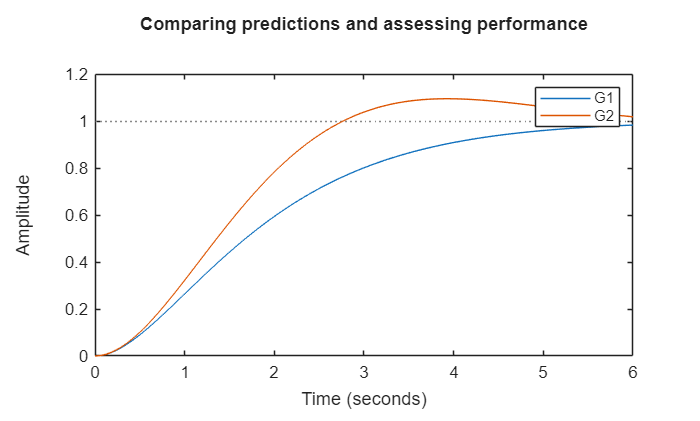

G1=tf(1,[1 2 1]);
G2 = tf(1,[1,1.2,1]);
step(G1,G2,6)
title('Comparing predictions and assessing performance')
legend('G1','G2')

The app described later will allow users to explore the impact of different choices of future inputs upon the predictions and determine whether such an approach is practical or sensible in general.

### 3.2 Automated decision making

In order to automate the decision making and ensure better consistency, we need some quantitative measure of best. Within the MPC community it is accepted that 2-norm performance measures have a number advantages over alternatives which make them the preferred option in general (a deeper discussion of this point is not appropriate in an introductory resource). Hence  consider the following measure for future performance:


$$J=\sum_{i=1}^{\textrm{ny}} {\left(r-y\left(k+i|k\right)\right)}^2 +\lambda \sum_{i=0}^{\textrm{nu}} \Delta u{\left(k+i|k\right)}^2 ;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=u\left(k\right)-u\left(k-1\right)$$


The parameters ny, nu and $\lambda$ are choices: over what horizon do you wish to assess the output predictions, how many changes to the input value will you be making in the predictions and how much do you weight input changes compared to prediction errors. In simple terms the MPC control law reduces to choosing, at every sample, the set of future input increments which minimises J.

Naturally the reader will notice several issues:

- This definition is somewhat arbitrary so we need to be honest about our use of the words best/optimal.

- The horizons and weights are degrees of freedom but impact significantly on the decision making. There are good and bad choices (not discussed here) but for now the app focuses on allowing users to investigate the core concept of 'optimised predictions'.

## 4. Interface and user interaction

The main purpose of the app is to allow users to visualise the prediction process and explore how changes in the decisions me make change the predictions. Users can then select the input trajectory which they like best before implementing it.

### 4.1 Main functions

The app has 2 main settings:

- **MPC**: In this setting all the predictions are automated (see section 3.2 and figure 4.1) and the app simply displays and implements these.

- **Manual**: The user can experiment with different choices of future input by changing the corresponding sliders. Each time a slider is changed the predictions will be updated in the plot. Note the number of sliders deployed matches the choice of control horizon (nu). See Figure 4.2.

Once the user is happy with the current prediction, they select the 'implement input' button to action this and move to the next sample. The App is set to do about 8 iterations/samples, that is, those covering the core transients. Users can exit at any time by pressing stop simulation. The figures below show the input and output predictions in dotted lines and the horizon in the green box (in the first MPC is selected and in the 2nd manual).

The bottom figure appears at the end of the simulation and shows the full MPC simulation for comparison purposes.

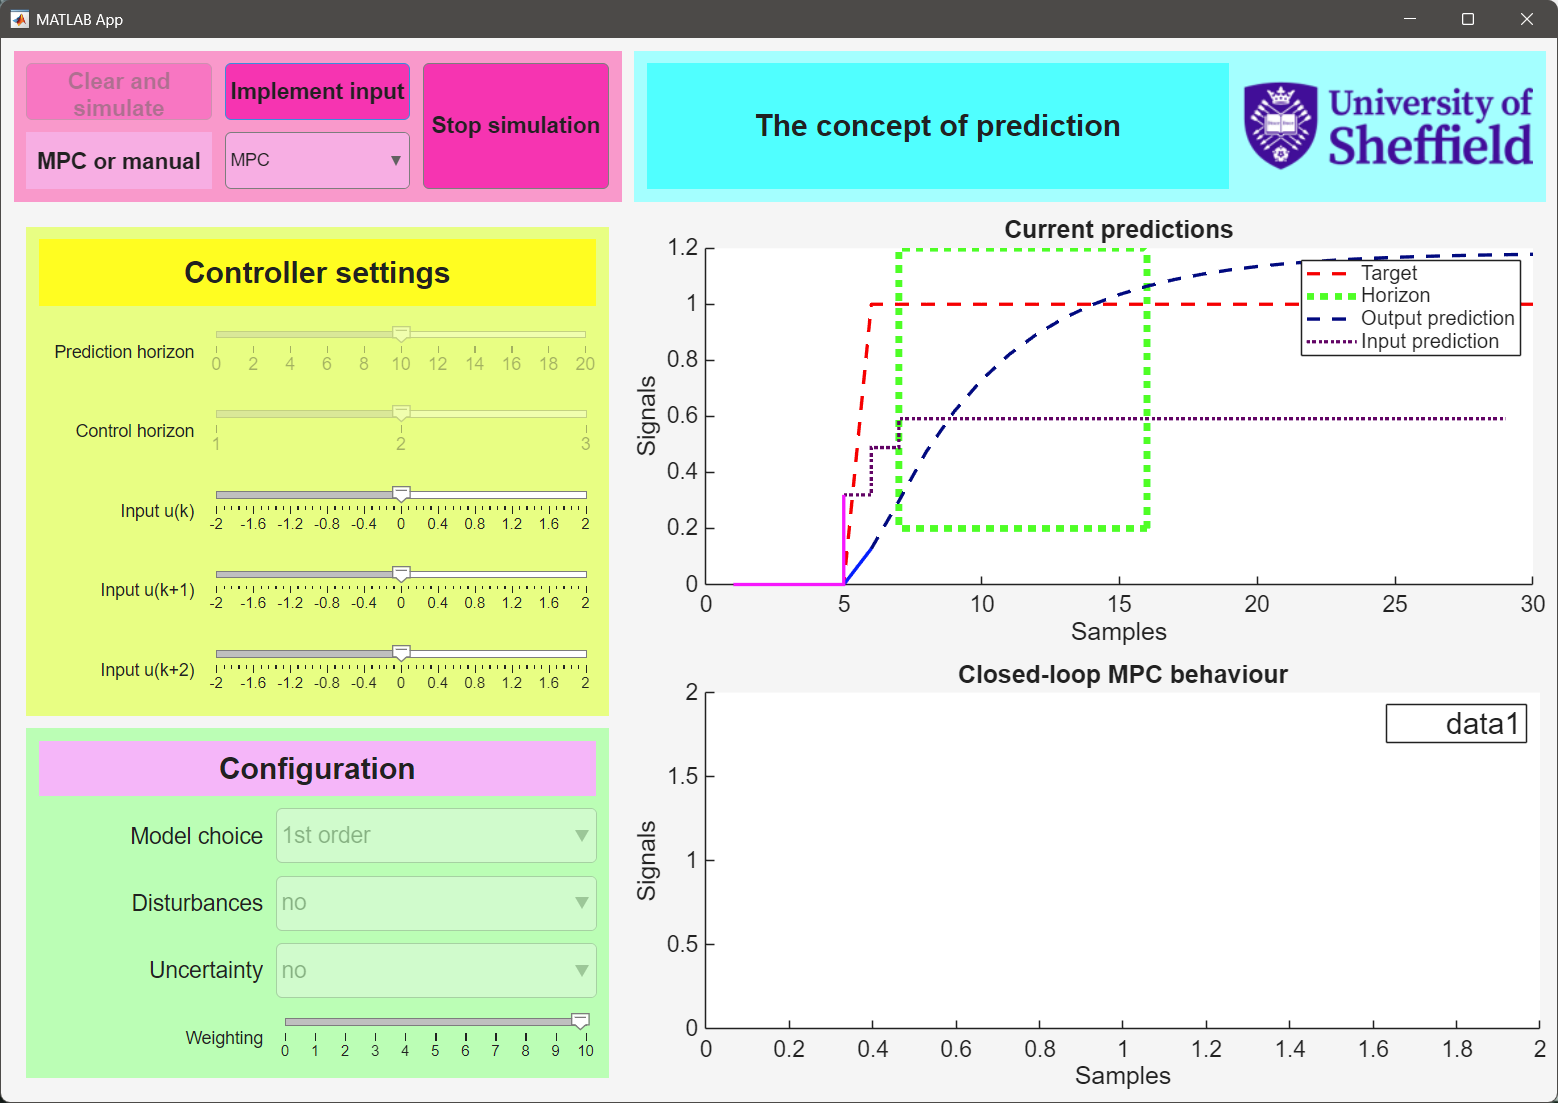

Figure 4.1 App in MPC mode

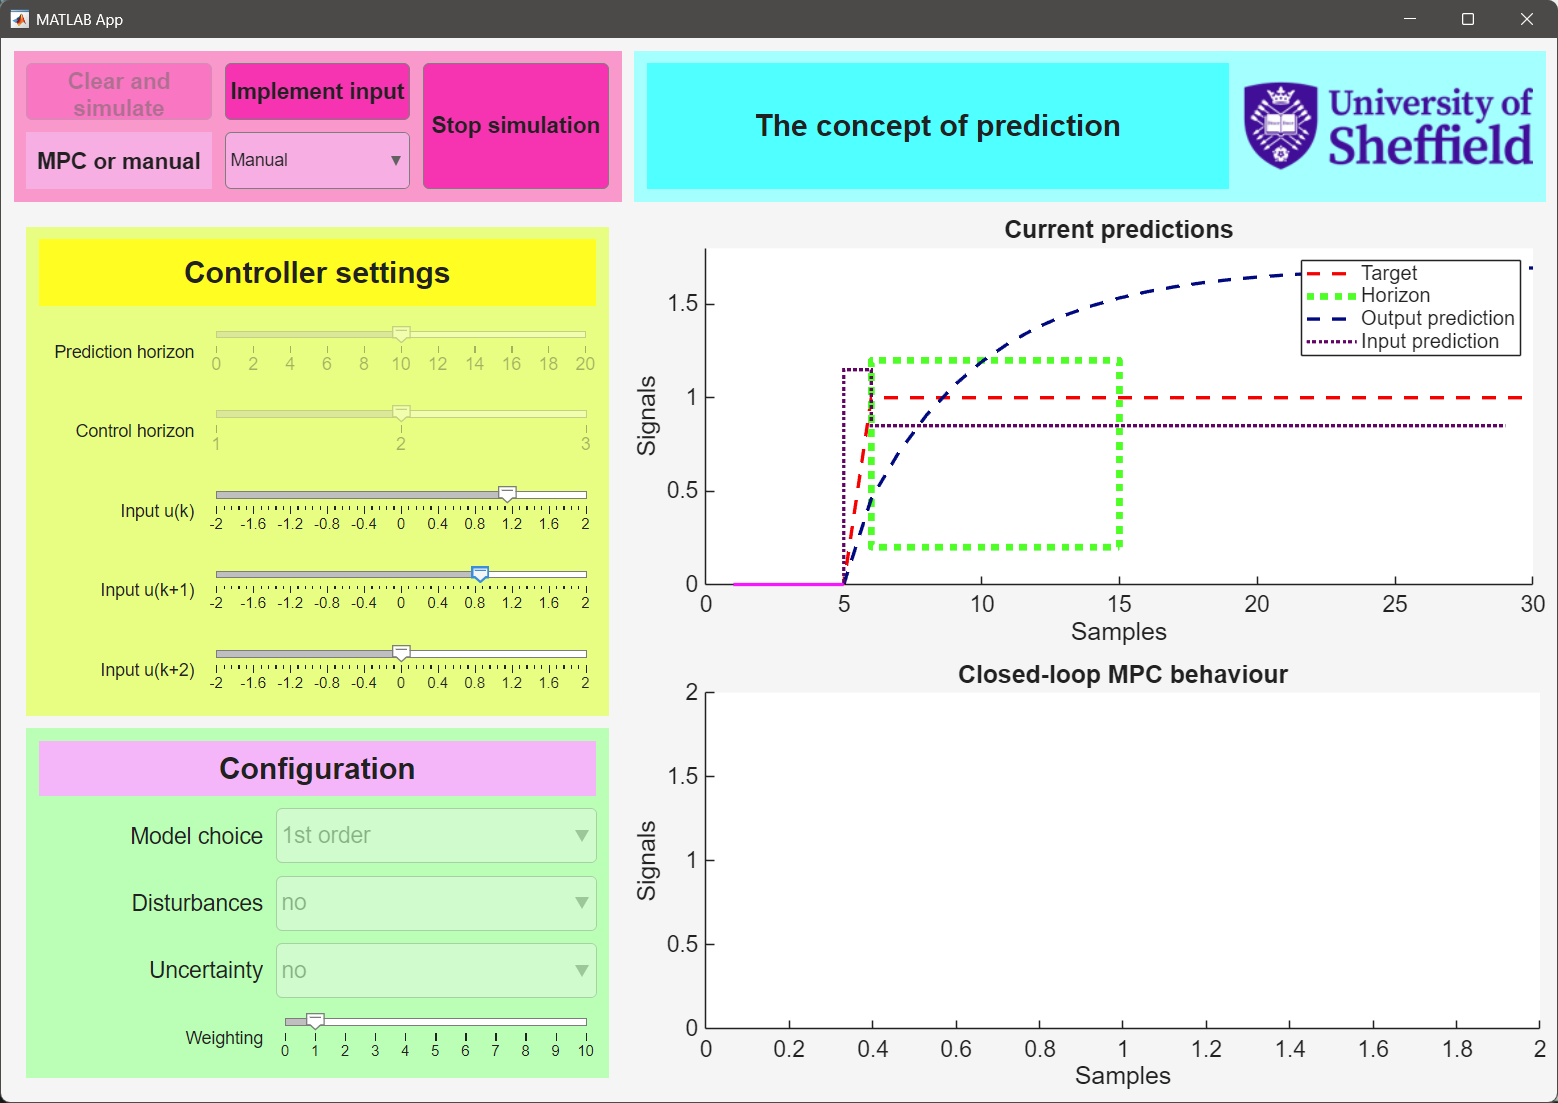

Figure 4.2 App in Manual mode

### 4.2 Tuning

The app also allows users to change the horizons ny, nu and the weighting $\lambda$. The range of choices is limited as the main purpose of the app is to explore and understand core concepts, not to complete a detailed and correct design. These settings need to be selected before beginning a simulation and will remain fixed during the simulation.

### 4.3 Uncertainty and model choices

The user can select from 3 different models of different orders. Again, the purpose of the app is to focus on concepts so these three examples should be ample.

The real world has lots of uncertainty, so for completeness this is also allowed.

- If disturbance is selected, this is assumed unknown until it has occured but users will notice (Figure 4.3) that temporarily the behaviour does not match the predictions and they will need to update their thinking.

- Users may not notice the detailed impact of parameter uncertainty, but in simple terms the actual behaviour will differ slightly from the predictions.

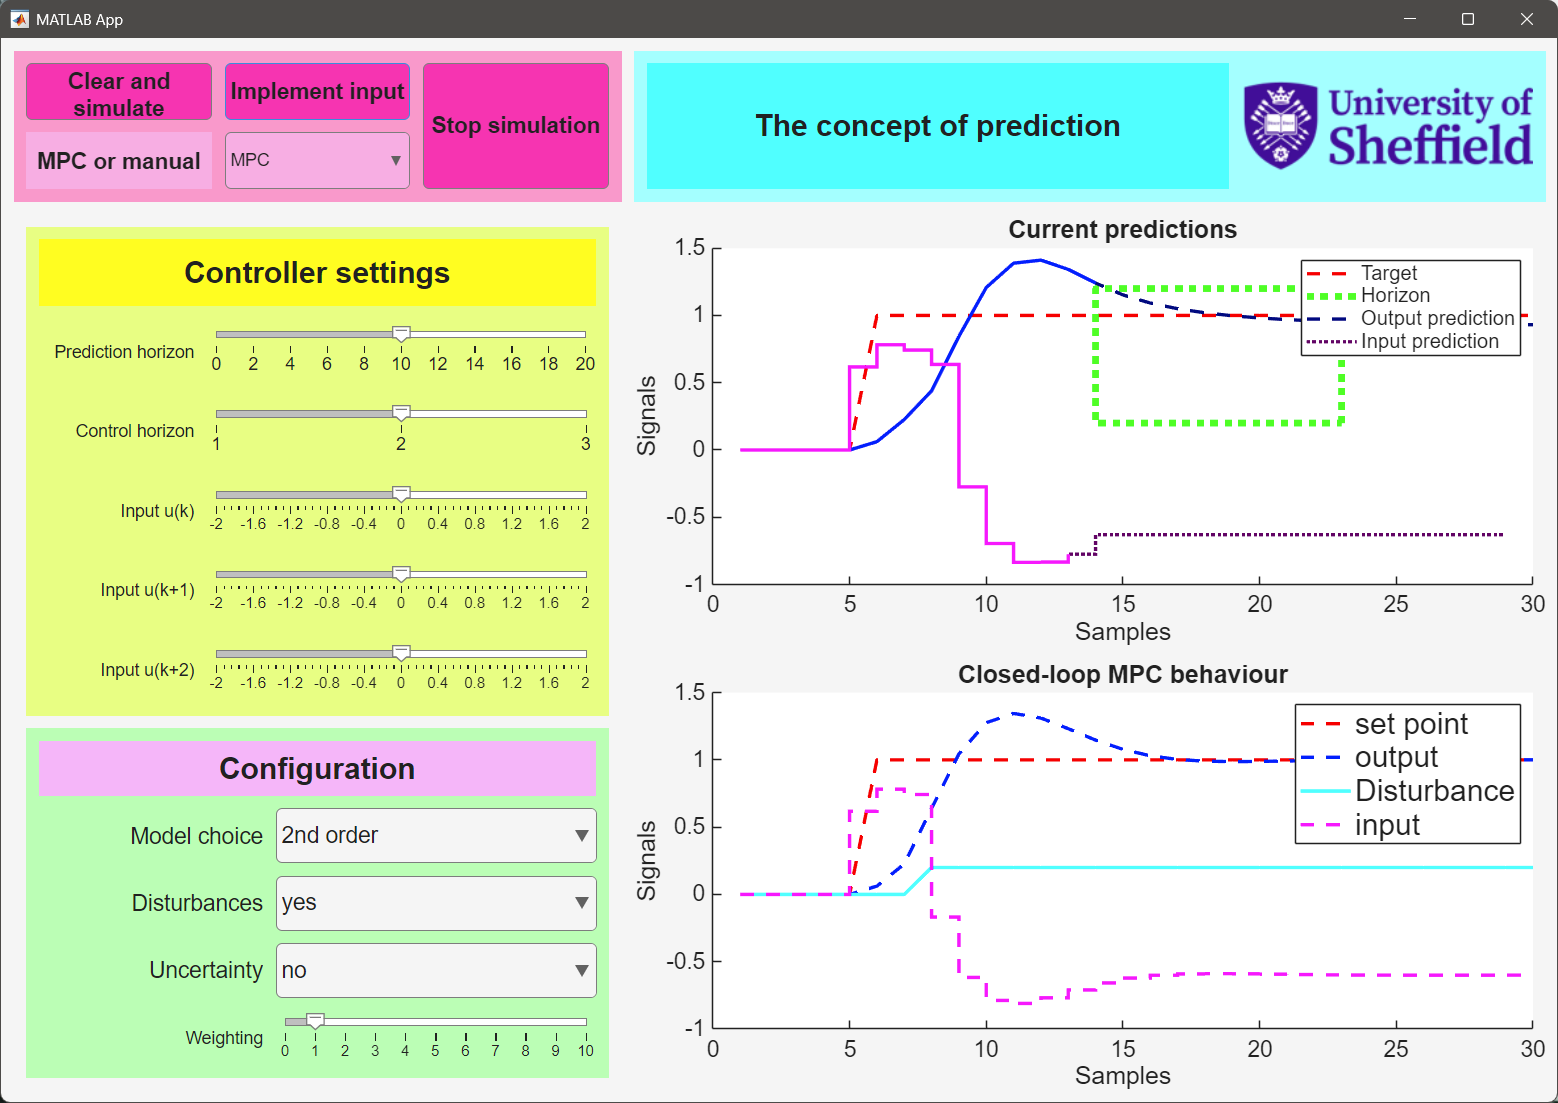

Figure 4.3 Impact of a disturbance